# MSessionExplorer.ResampleEventTimes

# MSessionExplorer.ResampleTimeSeries

Ignore code in this section

if exist('isRun', 'var') && exist('seRaw', 'var') && isRun
    se = seRaw.Duplicate;
    se.isVerbose = false;
    se.SetColumn('adc', 'tubeV', @(x) x-median(x), 'all');
    spk = se.GetTable('spikeTime');
    spk.Properties.VariableNames = arrayfun(@(x) ['unit' num2str(x)], 1:58, 'Uni', false);
    se.SetTable('spikeTime', spk);
else
    edit MSessionExplorer.Examples.ResampleEventTimes
    return;
end

**Description**

help MSessionExplorer.ResampleEventTimes

  Resample an eventTimes table to a timeSeries table by counting events in each bin
  
    tbOut = ResampleEventTimes(tbIn, tEdges)
    tbOut = ResampleEventTimes(tbIn, tEdges, rowInd)
    tbOut = ResampleEventTimes(tbIn, tEdges, rowInd, colInd)
    
  Inputs
    tbIn            A table of event times data or a name of an eventTimes table in the current object.
    tEdges          Edges of time bins. This can be one numeric vector that defines edges for every 
                    rows, or a cell array of vectors where each applies to a corresponding row. The 
                    number of element in cell array must equal the height of the table or the number 
                    of selected rows. 
    rowInd          Integer or logical indices of rows to operate on and return. The default value is 
                    empty indicating all rows. 
    colInd          Integer or logical indices of columns to operate on and return. It can 

help MSessionExplorer.ResampleTimeSeries

  Resample timeSeries table by interpolation
  
    tbOut = ResampleTimeSeries(tbIn, tEdges)
    tbOut = ResampleTimeSeries(tbIn, tEdges, rowInd)
    tbOut = ResampleTimeSeries(tbIn, tEdges, rowInd, colInd)
  
  Inputs
    tbIn            A table of time series data or a name of a timeSeries table in the current object.
    tEdges          Edges of time bins. This can be one numeric vector that defines edges for every 
                    rows, or a cell array of vectors where each applies to a corresponding row. The 
                    number of element in cell array must equal the height of the table or the number 
                    of selected rows. 
    rowInd          Integer or logical indices of rows to operate on and return. The default value is 
                    empty indicating all rows. 
    colInd          Integer or logical indices of columns to operate on and return. It can also be 
                    a cell array 

**Example 1**

**Resample data using a set of bins**

First, let's see how epochs are currently sliced. The plotted are the first 10 epochs in this session. Magenta rasters show 'unit1' events from 'spikeTime' table. Traces show 'tubeV' time series from 'adc' table. 

se.Preview('adc', 'spikeTime')

          time             lickportV           lickportH             tubeV               tubeH      
    ________________    ________________    ________________    ________________    ________________

    [13335×1 double]    [13335×1 single]    [13335×1 single]    [13335×1 single]    [13335×1 single]
    [11649×1 double]    [11649×1 single]    [11649×1 single]    [11649×1 single]    [11649×1 single]
    [14438×1 double]    [14438×1 single]    [14438×1 single]    [14438×1 single]    [14438×1 single]
    [ 8697×1 double]    [ 8697×1 single]    [ 8697×1 single]    [ 8697×1 single]    [ 8697×1 single]
    [ 9555×1 double]    [ 9555×1 single]    [ 9555×1 single]    [ 9555×1 single]    [ 9555×1 single]
    [ 9555×1 double]    [ 9555×1 single]    [ 9555×1 single]    [ 9555×1 single]    [ 9555×1 single]

        unit

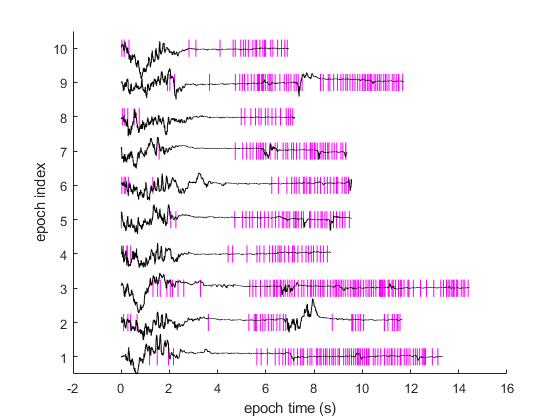

Visualize(se);

Now, we want to resample data between 0s and 10s with 0.2s per sample for each epoch. 

tEdges = 0 : .2 : 10;

spkRs = se.ResampleEventTimes('spikeTime', tEdges);
adcRs = se.ResampleTimeSeries('adc', tEdges);


It may seem strange why ResampleTimeSeries uses time bins to indirectly specify interpolation points (bin centers). By unifying the inputs of ResampleTimeSeries and ResampleEventTimes, we gurantee the outputs are always perfectly matched when using the same time bins. 

head(spkRs)

ans = 8×59 table
        time             unit1            unit2            unit3            unit4            unit5            unit6            unit7            unit8            unit9           unit10           unit11           unit12           unit13           unit14           unit15           unit16           unit17           unit18           unit19           unit20           unit21           unit22           unit23           unit24           unit25           unit26           unit27           unit28 

head(adcRs)

ans = 8×5 table
        time           lickportV        lickportH          tubeV            tubeH    
    _____________    _____________    _____________    _____________    _____________

    [50×1 double]    [50×1 single]    [50×1 single]    [50×1 single]    [50×1 single]
    [50×1 double]    [50×1 single]    [50×1 single]    [50×1 single]    [50×1 single]
    [50×1 double]    [50×1 single]    [50×1 single]    [50×1 single]    [50×1 single]
    [50×1 double]    [50×1 single]    [50×1 single]    [50×1 single]    [50×1 single]
    [50×1 double]    [50×1 single]    [50×1 single]    [50×1 single]    [50×1 single]
    [50×1 double]    [50×1 single]    [50×1 single]    [50×1 single]    [50×1 single]
    [50×1 double]    [50×1 single]    [50×1 single]    [50×1 single]    [50×1 single]
    [50×1 double]    [50×1 single]    [

spkRs.time{1}'

ans =     0.1000    0.3000    0.5000    0.7000    0.9000    1.1000    1.3000    1.5000    1.7000    1.9000    2.1000    2.3000    2.5000    2.7000    2.9000    3.1000    3.3000    3.5000    3.7000    3.9000    4.1000    4.3000    4.5000    4.7000    4.9000    5.1000    5.3000    5.5000    5.7000    5.9000    6.1000    6.3000    6.5000    6.7000    6.9000    7.1000    7.3000    7.5000    7.7000    7.9000    8.1000    8.3000    8.5000    8.7000    8.9000    9.1000    9.3000    9.5000    9.7000    9.9000


When resampling outside the bondaries of an epoch, ResampleEventTimes returns zeros (by definition the event count) but ResampleTimeSeries returns NaNs. To avoid this, please see example 3 for a better approach. (In a future version, they may both output NaN or provide options to users.)

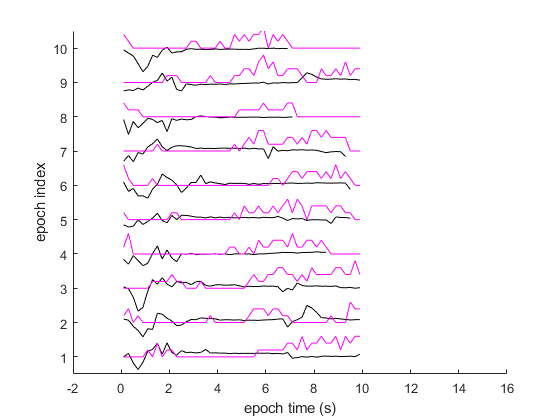

Visualize3(spkRs, adcRs);

**Example 2**

**Use different sets of bins to resample specific epochs and columns**

Please see Example 1 about the original data. Here, we create 5 sets of time bins to resample only 5 selected epochs, respectively, and 1 selected column. 

tEdges = {0:.2:2; 2:.2:4; 4:.2:6; 6:.2:8; 8:.2:10};
celldisp(tEdges)

 
tEdges{1} =
 
         0    0.2000    0.4000    0.6000    0.8000    1.0000    1.2000    1.4000    1.6000    1.8000    2.0000

 
 
tEdges{2} =
 
    2.0000    2.2000    2.4000    2.6000    2.8000    3.0000    3.2000    3.4000    3.6000    3.8000    4.0000

 
 
tEdges{3} =
 
    4.0000    4.2000    4.4000    4.6000    4.8000    5.0000    5.2000    5.4000    5.6000    5.8000    6.0000

 
 
tEdges{4} =
 
    6.0000    6.2000    6.4000    6.6000    6.8000    7.0000    7.2000    7.4000    7.6000    7.8000    8.0000

 
 
tEdges{5} =
 
    8.0000    8.2000    8.4000    8.6000    8.8000    9.0000    9.2000    9.4000    9.6000    9.8000   10.0000

 



row2slice = [1 3 5 7 9]'

row2slice =      1
     3
     5
     7
     9



spkRs = se.ResampleEventTimes('spikeTime', tEdges, row2slice, {'unit1'})

spkRs = 5×2 table
        time             unit1    
    _____________    _____________

    [10×1 double]    [10×1 double]
    [10×1 double]    [10×1 double]
    [10×1 double]    [10×1 double]
    [10×1 double]    [10×1 double]
    [10×1 double]    [10×1 double]


adcRs = se.ResampleTimeSeries('adc', tEdges, row2slice, {'tubeV'})

adcRs = 5×2 table
        time             tubeV    
    _____________    _____________

    [10×1 double]    [10×1 single]
    [10×1 double]    [10×1 single]
    [10×1 double]    [10×1 single]
    [10×1 double]    [10×1 single]
    [10×1 double]    [10×1 single]


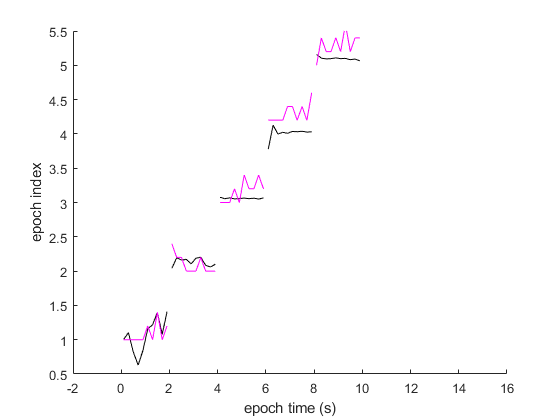


Visualize3(spkRs, adcRs);

**Example 3**

**Resample a table outside of the object**

To avoid resampling from periods where data is not available, we first slice data out using the 'bleed' option to fill in available data from other epochs. 

tWin = [0 10];
spk = se.SliceEventTimes('spikeTime', tWin, 'Fill', 'bleed');
adc = se.SliceTimeSeries('adc', tWin, 'Fill', 'bleed');


Now do the resampling. In general, the input tables can be arbitrary as long as they comply to the standards of eventTimes table and timeSeries table. 

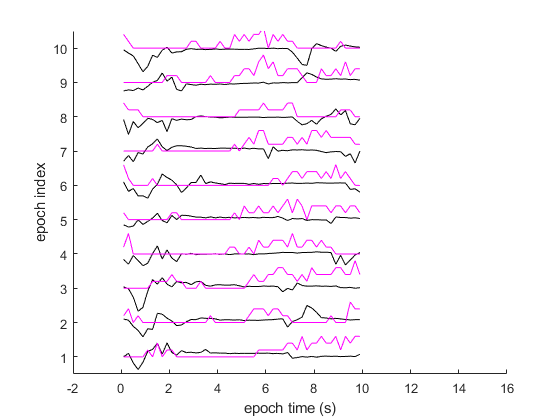

tEdges = tWin(1) : .2 : tWin(2);
spkRs = se.ResampleEventTimes(spk, tEdges);
adcRs = se.ResampleTimeSeries(adc, tEdges);

Visualize3(spkRs, adcRs);

**Helper functions**

function Visualize(se)
[spk, adc] = se.GetTable('spikeTime', 'adc');
Visualize2(spk, adc);
end

function Visualize2(spk, adc)
ind = 1:min(10, height(spk));
figure; clf
MPlot.PlotRaster(spk.unit1(ind), ind, 0.5, 'Color', 'm');
MPlot.PlotTraceLadder(adc.time(ind), adc.tubeV(ind), ind, 'Color', 'k');
xlim([-2 16]);
ylim([ind(1)-0.5 ind(end)+0.5]);
xlabel('epoch time (s)');
ylabel('epoch index');
box off
end

function Visualize3(spk, adc)
ind = 1:min(10, height(spk));
spk.unit1 = cellfun(@(x) x*0.2, spk.unit1, 'Uni', false);
figure; clf
MPlot.PlotTraceLadder(adc.time(ind), adc.tubeV(ind), ind, 'Color', 'k'); hold on
MPlot.PlotTraceLadder(spk.time(ind), spk.unit1(ind), ind, 'Color', 'm');
xlim([-2 16]);
ylim([ind(1)-0.5 ind(end)+0.5]);
xlabel('epoch time (s)');
ylabel('epoch index');
box off
end